# **PGD Approximation of a random space-time field **

# **- A POSTERIORI-**

*Eren Alagoz, adapted from V. Matray's training sessions*

clear all
close all
clc

## Time discretisation

T   = 10; 
n_T = 400; 
tf  = linspace(0,T,n_T);     % fine discretisation
tc  = linspace(0,T,n_T/10);  % coarse discretisation
dt  = tf(2); % time step

## Space discretisation

L = 1; 
n_X = 200; 
xf  = linspace(0,L,n_X);    % fine discretisation
xc  = linspace(0,L,n_X/10); % coarse discretisation
dx  = xf(2);

## Display of the field smoothed to approximated by PGD 

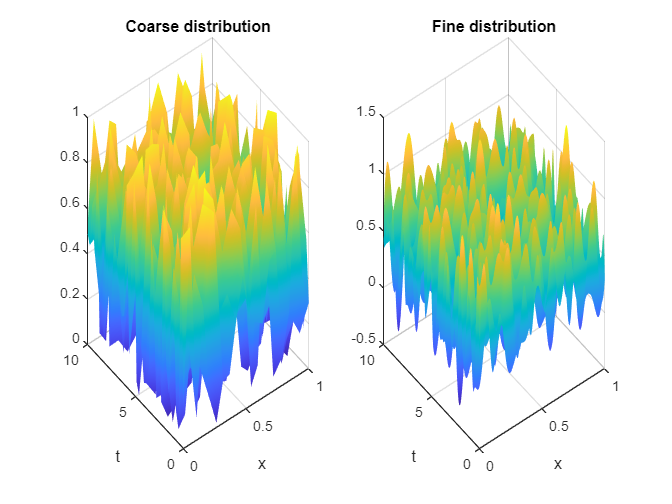

% Meshes (fine and coarse)
[mesh_x_f,mesh_t_f] = meshgrid(xf,tf);
[mesh_x_g,mesh_t_g] = meshgrid(xc,tc);

% Random function on the coarse mesh:
Ug = rand(n_T/10,n_X/10);

% Interpolation on the fine mesh to get a 
% smooth distribution : (If the field is too discontinuous
% the PGD will have trouble approximating it: 
% you can check this at the end of the session).

Uf = interp2(mesh_x_g,mesh_t_g,Ug,mesh_x_f,mesh_t_f,'spline');

% Display distribution
figure()
subplot(1,2,1)
surf(xc,tc,Ug)
xlabel('x')
ylabel('t')
title("Coarse distribution")
shading interp

subplot(1,2,2)
surf(xf,tf,Uf)
xlabel('x')
ylabel('t')
title("Fine distribution")
shading interp

## Operators for calculating integrals (spatial and temporal) 

%TO DO
%direct
I_x = (dx/6) * (2*diag(ones(n_X,1)) + diag(ones(n_X-1,1),1) + diag(ones(n_X-1,1),-1));
I_t = (dt/6) * (2*diag(ones(n_T,1)) + diag(ones(n_T-1,1),1) + diag(ones(n_T-1,1),-1));

%boucle
Ib_x = zeros(n_X);
Ib_t = zeros(n_T);
Ie_x = dx * [1/3 , 1/6 ; 1/6 , 1/3];
Ie_t = dt * [1/3 , 1/6 ; 1/6 , 1/3];
for i = 1:(n_X - 1)
    Ib_x(i:i+1 , i:i+1) = Ib_x(i:i+1 , i:i+1) + Ie_x;
end
for i = 1:(n_T - 1)
    Ib_t(i:i+1 , i:i+1) = Ib_t(i:i+1 , i:i+1) + Ie_t;
end

## PGD Approximation of Uf

% Number of modes
n_modes    = 20;

% initialisation
Lambda     = zeros(n_X,n_modes);
Gamma      = zeros(n_T,n_modes);
U_PGD      = zeros(n_T,n_X);
PGD_error = zeros(n_modes,1);

## Greedy algorithm + fixed point 

for mode = 1:n_modes
    
    U_PGD = Gamma*Lambda'; % look at dimensions !
    DeltaU = (Uf - U_PGD)';
    % Add new mode
    % Initialize new time function Gamma
    Gamma_m = rand(n_T,1);
    
    % Fixed point algorithm
    s = 100;
    tol = 1e-3; 

    while s > tol
        
      
        % Save old time function Gamma
        Gamma_old = Gamma_m;
        
        % Compute new space function Lambda
        Lambda_new = (DeltaU * Ib_t * Gamma_m) / (Gamma_m' * Ib_t * Gamma_m);
        
        % Normalisation
        normL = sqrt(Lambda_new' * Ib_x * Lambda_new);
        Lambda_new = Lambda_new/normL;
        
        % Compute new time function Gamma
        Gamma_new = (DeltaU' * Ib_x * Lambda_new) / (Lambda_new' * Ib_x * Lambda_new);
        
        % update stagnation criteria
        s = ((Gamma_new - Gamma_old)' * Ib_t * (Gamma_new - Gamma_old))/(Gamma_old' * Ib_t * Gamma_old);
    
    end
    

    % Orthogonalisation
     %We'll do this after we've successfully run the greedy
     % algorithm and managed to calculate the error in 
     % space-time. All we need to do here is to implement 
     % the Gram-Schmidt algorithm.
     % Note that mode orthogonalization is not useful here,
     % but it will be in the next TP 
     % (a priori use of the PGD).


    % store the new modes
    Gamma(:,mode) = Gamma_new;
    Lambda(:,mode) = Lambda_new;
    % compute the new PGD approximation with the added mode
    U_PGD = Gamma*Lambda';
    
    % Calculation of the reconstruction error with the spatio-temporal norm
    err = zeros(n_X,1);
    norm_U_t = zeros(n_X,1);
    % Integration temporelle
    for i = 1:n_X
        err(i) = sqrt(DeltaU' * Ib_t * DeltaU);
        norm_U_t = sqrt(Uf' * Ib_t * DeltaU);
    end
    PGD_error(mode) = sqrt((err' * Ib_x * err)/(norm_U_t' * Ib_x * norm_U_t));

    surf(mesh_x_f,mesh_t_f,U_PGD)
     xlabel('x')
     ylabel('y')
     zlabel('U PGD')
     shading interp
     Title = ["Approximation with "+ mode " mode(s)"];
     title(Title)
     pause
end 
